# 5 bars Robot Direct

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs

S0=[0;1;0];  % gripper first position
S1=[1;0.75;0.3];     % gripper final position

dS = S1 - S0;
T = 5;
n = 100;
dT = T/(n-1);


### 2) The robot moves linearly in joint coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


close all
figure(1)

Plot the workspace

% Plot workspace
center_x = 0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius*cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)
center_x = l0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)

center_x = 0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')

center_x = l0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')
axis equal
grid on

Plot the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


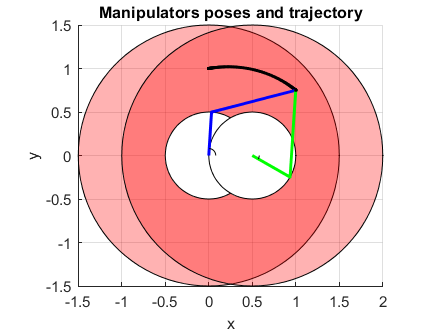

Q_ini = inverse_kinematics(S0,L,[130*pi/180 50*pi/180]);
Q_fin = inverse_kinematics(S1,L,[130*pi/180 50*pi/180]);

dQ = Q_fin - Q_ini;

for i = 1:n
    t = (i-1)*dT;
    tt(i) = t;
    [q(i,:) qp(i,:) qpp(i,:)] = cycloidal(t,T,Q_ini,dQ);
    
    if i==1
        guess = [0 80*pi/180];
    else
        guess = s(i-1,:);
    end
    
    s(i,:) = direct_kinematics(q(i,:),L,guess);
    [J, J_s, J_q] = Jacobian(s(i,:),q(i,:),L);
    v(i,:) = inv(J)*qp(i,1:2)';
    a(i,:) = -inv(J_s)*(Jp_s(q(i,1:2),qp(i,1:2),v(i,:),L)*v(i,:)'+Jp_q(s(i,:),q(i,1:2),qp(i,1:2),v(i,:),L)*qp(i,1:2)'+J_q*qpp(i,1:2)');

    [config1, theta(i)] = plot2D_1st(q(i,:),L,1,s(i,1),s(i,2));
    [config2, gamma(i)] = plot2D_2nd(q(i,:),L,1,s(i,1),s(i,2));

    plot(s(i,1),s(i,2),'.-black')
    % Plot the angle arc
    h1 = plotAngleArc([0,0],0.08,[0,q(i,1)],'k-',1); %alfa
    h2 = plotAngleArc([l0,0],0.08,[0,q(i,2)],'k-',1); %beta

    pause(dT)
    if i==n
        break
    end
    delete(config1); delete(config2); delete(h1); delete(h2);
    hold off
    title('Manipulators poses and trajectory');
    xlabel('x')
    ylabel('y')
end

hold off

### 3D Plot

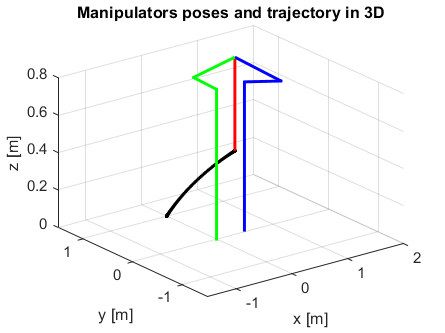

close all
figure(2)
plot3(0,0,0,'LineWidth',4,'color','red') 
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+l2]);
zlim([0,h]);
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on
for i=1:n
    % Print
    config1 = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    config2 = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dT)
    if i==n
        break
    end
    delete(config1); delete(config2); delete(config3)
end
hold off

### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

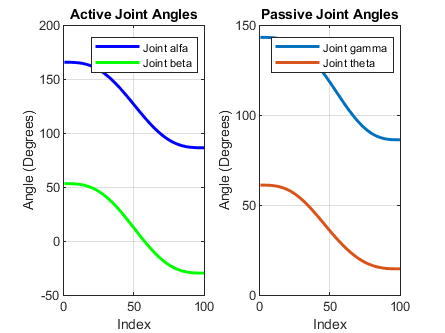

figure(2)
% alpha e beta
subplot(1,2,1)
plot(q(:,1)*180/pi,'b','LineWidth',2);
hold on
plot(q(:,2)*180/pi,'g','LineWidth',2);
hold off
title('Active Joint Angles')
xlabel('Index')
ylabel('Angle (Degrees)')
grid on
legend('Joint alfa','Joint beta')

% gamma e theta
subplot(1,2,2)
plot(gamma*180/pi,'LineWidth',2);
hold on
plot(theta*180/pi,'LineWidth',2);
hold off
title('Passive Joint Angles')
xlabel('Index')
ylabel('Angle (Degrees)')
grid on
legend('Joint gamma','Joint theta')

### 1b) Joint motion

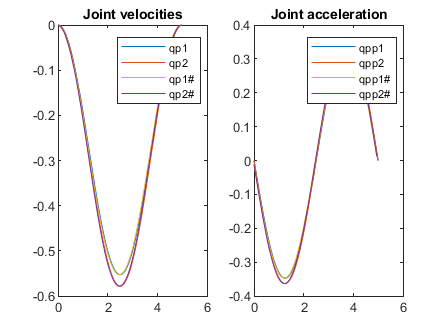

figure(3)
qp_alfa_debug = diff(q(:,1))/dT;
qp_beta_debug = diff(q(:,2))/dT;

qpp_alfa_debug = diff(qp(:,1))/dT;
qpp_beta_debug = diff(qp(:,2))/dT;

subplot(1,2,1)
plot(tt,qp(:,1),tt,qp(:,2),tt(1:end-1),qp_alfa_debug,tt(1:end-1),qp_beta_debug);
legend('qp1','qp2','qp1#','qp2#');
title('Joint velocities')
subplot(1,2,2)
plot(tt,qpp(:,1),tt,qpp(:,2),tt(1:end-1),qpp_alfa_debug,tt(1:end-1),qpp_beta_debug);
legend('qpp1','qpp2','qpp1#','qpp2#')
title('Joint acceleration')

### 2) Dynamics


$$F_q = ({J_e}^t M J_e)\ddot{Q}+{J_e}^tM\dot{J_e}\dot{Q}-{J_e}^tF_{se}$$



Je_0 = Jacobian_Ext(q(1,:),L,G,J);
for i = 2:n
    if i==2
        Je=Jacobian_Ext(q(i,:),L,G,J);
        Jep = (Je-Je_0)./dT;
    else
        Je_0=Jacobian_Ext(q(i-1,:),L,G,J);
        Je=Jacobian_Ext(q(i,:),L,G,J);
        Jep = (Je-Je_0)./dT;
    end
    
    Fq(i,:) = (Je'*M*Je)*qpp(i,1:2)' + (Je'*M*Jep)*qp(i,1:2)'-transpose(Je)*Fse;
    
    Se=direct_dynamics(q(i,:),s(i,:),L,G);
    Sep(:,i) = Je*qp(i,1:2)';
    Ek(i,:) = (1/2)*Sep(:,i)'*M*Sep(:,i);
    Ep(i,:) = transpose(Ag)*M*Se;
    E_tot(i,:) = Ep(i,:) + Ek(i,:);
    W(i,:)=qp(i,1:2)*Fq(i,:)'+Sep(:,i)'*Fse;
    

end


### 2a) Actuator torques

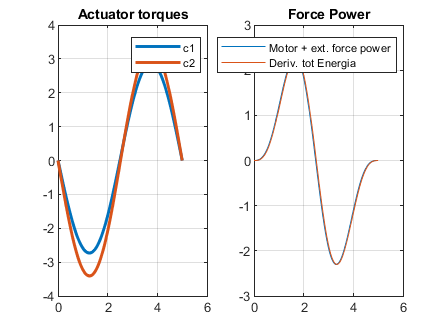

figure(5)
subplot(1,2,1)
plot(tt,Fq(:,1),tt,Fq(:,2),'LineWidth',2)
title("Actuator torques")
legend('c1','c2')
grid on

subplot(1,2,2)
W_debug = diff(E_tot)/dT;
plot(tt(1:end-1),W_debug);
hold on
plot(tt,W);
hold off
title("Force Power")
legend('Motor + ext. force power', 'Deriv. tot Energia')
grid on